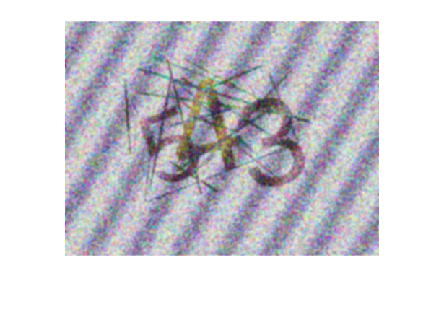

I= imread('Train/captcha_0001.png');
imshow(I)

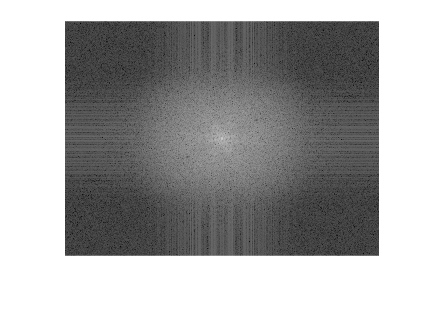

I_gray = rgb2gray(I);

fft = fft2(double(I_gray));
fftshifted = fftshift(fft);

magnitude= log(abs(fftshifted) + 1);
imshow(magnitude, []);

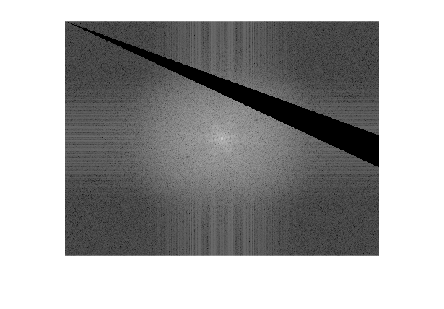


[rows, cols]=size(magnitude);

tan_range = tan(deg2rad([65, 70]));

for i=1:rows
    for j=1:cols
        tangent=j/i;
        if tangent>tan_range(1) && tangent<tan_range(2) 
            fftshifted(i,j)=0;
        end 
    end 
end 
magnitudeSpectrum = log(abs(fftshifted) + 1);
imshow(magnitudeSpectrum, []);